init_unfold


Adding toolboxes and subfolders to path... 


projectFolder = '/net/store/nbp/users/behinger/projects/deconvolution';
%% Load the data
tmp = load(fullfile(projectFolder,'cache/n400_2nd.mat'));
d2nd = tmp.d2nd;

## Plot a single channel

plotting all parameters


performing baseline correction 
performing baseline correction 


plotting all parameters


performing baseline correction 
performing baseline correction 
New X or Y of different size given, all data from first gramm cleared


ans =   gramm with properties:

     legend_axe_handle: [1×1 Axes]
      title_axe_handle: []
    facet_axes_handles: [2×5 Axes]
               results: [1×1 struct]


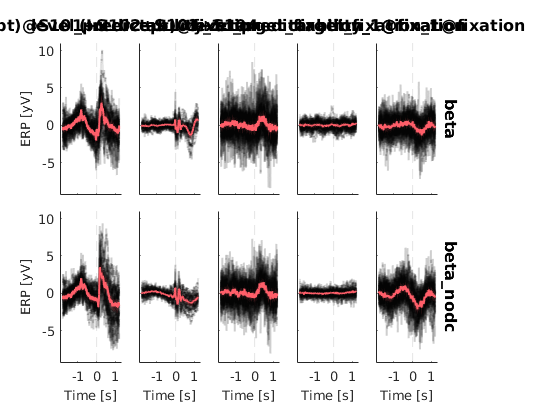

%% plot deconv vs nodeconv
% This does not work with splines 
cfg = [];
cfg.channel = 40; % Pz = 32
cfg.add_intercept = 0;
cfg.baseline = [min(d2nd.times) 0];

dc_plot2nd(d2nd,cfg);

## Statistics using Threshold-Free-Cluster-Enhancement (TFCE)

ept_tfce_nb =      1     3     8    13    22     0     0     0     0
     2     4    12    21    28     0     0     0     0
     1     3     5     6     8     0     0     0     0
     2     4     6     7    12     0     0     0     0
     3     5     6     8     9     0     0     0     0
     3     4     5     6     7     9    10    11     0
     4     6     7    11    12     0     0     0     0
     1     3     5     8     9    13    14     0     0
     5     6     8     9    10    14    15    16     0
     6     9    10    11    16    17    18     0     0
     6     7    10    11    12    18    19    20     0
     2     4     7    11    12    20    21     0     0
     1     8    13    14    22    23    29     0     0
     8     9    13    14    15    23    24     0     0
     9    14    15    16    24     0     0     0     0
     9    10    15    16    17    24    25    32     0
    10    16    17    18    25     0     0     0     0
    10    11    17    18    19    25    26    34   

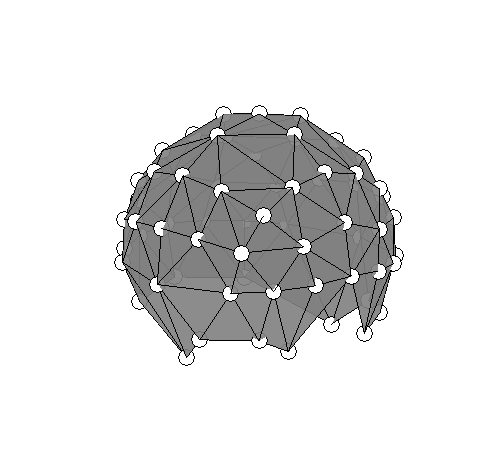

% This function calculates a channel matrix that can be used for default cluster-permutation tests
% using the ept-TFCE toolbox
ept_tfce_nb = ept_ChN2(d2nd.chanlocs,1) % the 1 to plot

% Average amount of neighbours:
mean(sum(ept_tfce_nb'>0))

ans =        5.5938


Run the analysis using the ept-tfce toolbox

cfg = [];
cfg.chan = 1:63; % the other channels are eye-movement channels from the Eye-EEG toolbox
cfg.pred = 4; % predictability at a target-word

% subselect channels & predictor  
data = squeeze(d2nd.beta(cfg.chan,:,cfg.pred,:));

% baseline correction
data = bsxfun(@minus,data,mean(data(:,d2nd.times<0,:),2));

% do the statistics
% this is a customized version of the original ept_tfce_diff function
[res,info] = be_ept_tfce_diff(struct('nperm',500,'neighbours',ept_tfce_nb(cfg.chan,:)),permute(data,[3 1 2]));

Calculating Actual Differences...


Calculating Permutations...


Done


Calculating P-Values and Saving...


All done!


Elapsed time is 73.376419 seconds.


Peak significance found at channel 48 at sample 1134: max-t-val(24) = 6.037, p = 0.001992


These results are now corrected for multiple comparisons of electrode x time. They are not corrected for multiple tests one might perform on the data.

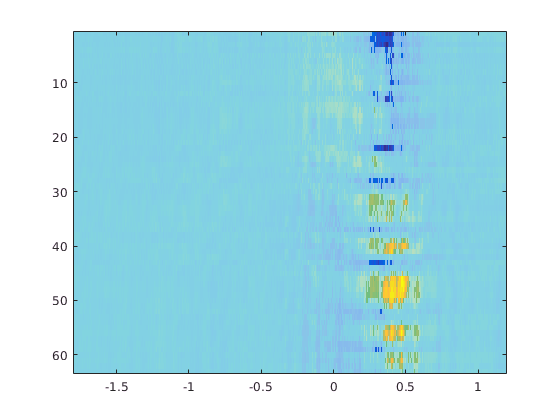

% plot it
figure,
h = imagesc(d2nd.times,1:63, res.TFCE_Obs);
set(h,'AlphaData',(res.P_Values<0.05)*0.5+0.5)

This gives a complete picture of where effects are. But the spatial relations are not easily accessible. Topoplots are another way to display this data.

Plotting Topoplots ... Elapsed time is 0.000297 seconds.


Elapsed time is 0.358530 seconds.


Elapsed time is 0.193594 seconds.


Elapsed time is 0.204268 seconds.


Elapsed time is 0.204011 seconds.


Elapsed time is 0.212305 seconds.


Elapsed time is 0.217514 seconds.


Elapsed time is 0.212385 seconds.


Elapsed time is 0.247328 seconds.


Elapsed time is 0.216414 seconds.


Elapsed time is 0.217188 seconds.


Elapsed time is 0.227991 seconds.


Elapsed time is 0.232560 seconds.


Elapsed time is 0.241134 seconds.


Elapsed time is 0.236643 seconds.


1.02s for row 1/3
Plotting Topoplots ... Elapsed time is 0.000017 seconds.


Elapsed time is 0.270511 seconds.


Elapsed time is 0.273747 seconds.


Elapsed time is 0.286562 seconds.


Elapsed time is 0.295593 seconds.


Elapsed time is 0.293765 seconds.


Elapsed time is 0.302983 seconds.


Elapsed time is 0.304064 seconds.


Elapsed time is 0.327282 seconds.


Elapsed time is 0.345243 seconds.


Elapsed time is 0.340354 seconds.


Elapsed time is 0.351449 seconds.


Elapsed time is 0.351757 seconds.


Elapsed time is 0.363332 seconds.


Elapsed time is 0.358539 seconds.


1.14s for row 2/3
Plotting Topoplots ... Elapsed time is 0.000019 seconds.


Elapsed time is 0.358107 seconds.


Elapsed time is 0.407306 seconds.


Elapsed time is 0.398657 seconds.


Elapsed time is 0.407759 seconds.


Elapsed time is 0.422757 seconds.


Elapsed time is 0.427921 seconds.


Elapsed time is 0.445103 seconds.


Elapsed time is 0.453831 seconds.


Elapsed time is 0.454447 seconds.


Elapsed time is 0.456891 seconds.


Elapsed time is 0.479970 seconds.


Elapsed time is 0.474116 seconds.


Elapsed time is 0.481525 seconds.


Elapsed time is 0.463212 seconds.


1.58s for row 3/3


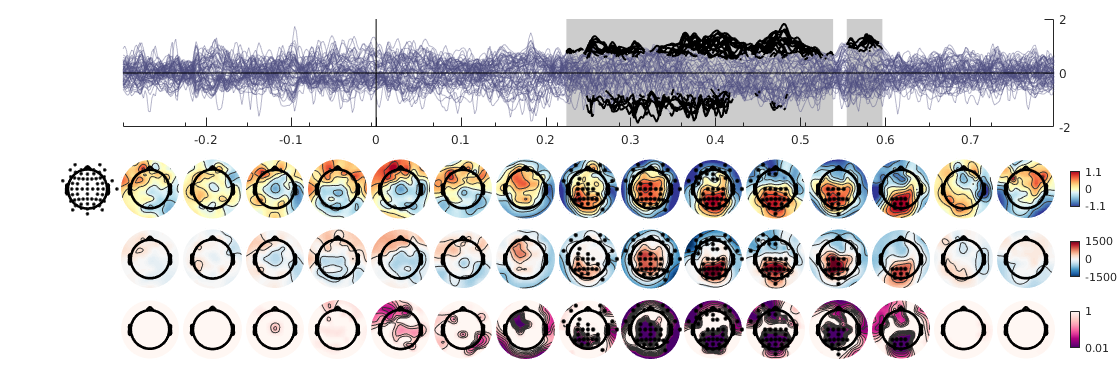

cfgPlot = [];
cfgPlot.pvalues = res.P_Values;
cfgPlot.colormap = {{'div','RdYlBu'},{'div','RdBu'},'seq'};
cfgPlot.topoalpha = 0.05; % where to put the significance dots?
cfgPlot.individualcolorscale = 'row'; % different rows have very different interpretation
cfgPlot.time = [-0.3 0.8]; % we will zoom in

plot_topobutter(cat(3,mean(data(1:63,:,:),3),res.TFCE_Obs,res.P_Values),d2nd.times,d2nd.chanlocs(1:63),cfgPlot)

This concludes the tutorial on doing group level analyses. 